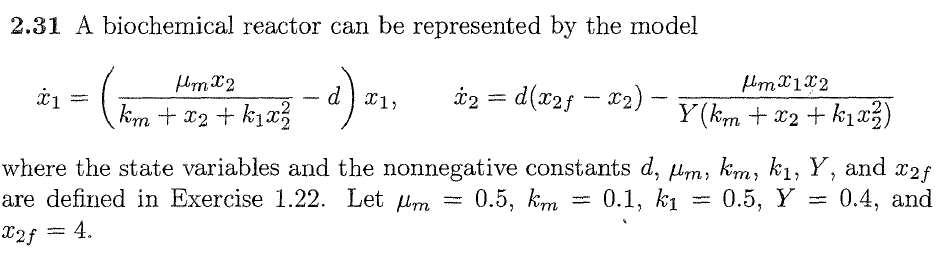

close all; clc

mu = 0.5;
km = 0.1;
k1 = 0.5;
capY = 0.4;
x2f = 4;

syms x1 x2 real
syms d positive
f1 = (mu*x2/(km+x2+k1*x2^2)-d)*x1
f2 = d*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2))

sln = solve([f1 f2], [x1 x2],'ReturnConditions',true);
sln.x1
sln.x2
sln.conditions

% number of equilibrium points as "d" varies
close all;
dd = linspace(0.01, 1, 20);
for d=dd
    g1 = (mu*x2/(km+x2+k1*x2^2)-d)*x1;
    g2 = d*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));
    
    sln = solve([g1 g2], [x1 x2]);
    plot(d,numel(sln.x1), 'bo'); hold on;

end
title('Num Equilibrium Points')
xline([5/8+sqrt(5)/8, 5/8-sqrt(5)/8], 'k--')
xlabel('d')
hold off

% plot the eigenvalues for various "d" for solution (1)
close all;
dd = linspace(0.1, 1, 20);
L1 = zeros(size(dd));
L2 = zeros(size(dd));

j=1;
for d=dd 
    g1 = (mu*x2/(km+x2+k1*x2^2)-d)*x1;
    g2 = d*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));
    
    sln = solve([g1 g2], [x1 x2]);
    J = jacobian([g1 g2], [x1 x2]);

    A = subs(J, [x1 x2], [sln.x1(1) sln.x2(1)]); % (1)
    L = eig(A);
    L1(j) = L(1);
    L2(j) = L(2);
    j=j+1;
end
yline(0,'k-'); hold on;
plot(dd,L1, 'r');
plot(dd,L2, 'b');
title('Eigenvalues - (1)')
xlabel('d')
grid on
hold off

% plot the eigenvalues for various "d" for solution (2)
close all;
% dd = linspace(0.001, 0.34, 20);
dd = linspace(0.9046,1,20);

L1 = zeros(size(dd));
L2 = zeros(size(dd));

j=1;
for d=dd 
    g1 = (mu*x2/(km+x2+k1*x2^2)-d)*x1;
    g2 = d*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));
    
    sln = solve([g1 g2], [x1 x2]);
    J = jacobian([g1 g2], [x1 x2]);

    A = subs(J, [x1 x2], [sln.x1(2) sln.x2(2)]); % (2)
    L = eig(A);
    L1(j) = L(1);
    L2(j) = L(2);
    j=j+1;
end
yline(0,'k-'); hold on;
plot(dd,L1, 'r');
plot(dd,L2, 'b');
title('Eigenvalues - (2)')
xlabel('d')
grid on
hold off

% plot the eigenvalues for various "d" for solution (3)
close all;
% dd = linspace(0.001, 0.345, 20);
dd = linspace(0.9046,1,20);

L1 = zeros(size(dd));
L2 = zeros(size(dd));

j=1;
for d=dd 
    g1 = (mu*x2/(km+x2+k1*x2^2)-d)*x1;
    g2 = d*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));
    
    sln = solve([g1 g2], [x1 x2]);
    J = jacobian([g1 g2], [x1 x2]);

    A = subs(J, [x1 x2], [sln.x1(3) sln.x2(3)]); % (3)
    L = eig(A);
    L1(j) = L(1);
    L2(j) = L(2);
    j=j+1;
end
yline(0,'k-'); hold on;
plot(dd,L1, 'r');
plot(dd,L2, 'b');
title('Eigenvalues - (3)')
xlabel('d')
grid on
hold off

# Bifurcation Diagram

d = linspace(0.01, 1.5, 100);

% equilibrium points
e1 = vecnorm([0*d; 0*d+4]);
e2 = vecnorm([8/5 - (sqrt(5)*sqrt(16*d.^2-20*d+5)-10*d+5)./(25*d); ...
              (sqrt(5)*sqrt(16*d.^2-20*d+5)-10*d+5)./(10*d)]);
e3 = vecnorm([8/5 + (sqrt(5)*sqrt(16*d.^2-20*d+5)+10*d-5)./(25*d); ...
              -(sqrt(5)*sqrt(16*d.^2-20*d+5)+10*d-5)./(10*d)]);

close all;
e1_stable = zeros(size(d));
e2_stable = zeros(size(d));
e3_stable = zeros(size(d));

for i=1:length(d)

    g1 = (mu*x2/(km+x2+k1*x2^2)-d(i))*x1;
    g2 = d(i)*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));
    
    sln = solve([g1 g2], [x1 x2]);
    J = jacobian([g1 g2], [x1 x2]);

    % eq 1
    A = subs(J, [x1 x2], [sln.x1(1) sln.x2(1)]);
    L = real(eig(A));
    e1_stable(i) = max(L) < 0;
    
    if length(sln.x1) == 3

        % eq 2
        A = subs(J, [x1 x2], [sln.x1(2) sln.x2(2)]);
        L = real(eig(A));
        e2_stable(i) = max(L) < 0;

        % eq 3
        A = subs(J, [x1 x2], [sln.x1(3) sln.x2(3)]);
        L = real(eig(A));
        e3_stable(i) = max(L) < 0;

    else
        e2(i) = nan;
        e3(i) = nan;
    end
end

e1_stable = logical(e1_stable);
e2_stable = logical(e2_stable);
e3_stable = logical(e3_stable);

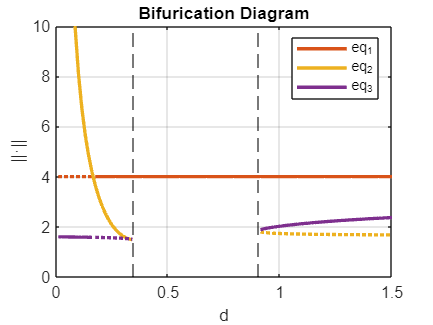

% plot the bifurication diagram
close all;

plot(d(e1_stable), e1(e1_stable), '-', ...
    'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2); hold on;
plot(d(~e1_stable), e1(~e1_stable), ':', ...
    'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2);

plot(d(e2_stable), e2(e2_stable), '-', ...
    'Color', [0.9290, 0.6940, 0.1250], 'LineWidth', 2);
plot(d(~e2_stable), e2(~e2_stable), ':', ...
    'Color', [0.9290, 0.6940, 0.1250], 'LineWidth', 2);

plot(d(e3_stable & d < (5-sqrt(5))/8), e3(e3_stable & d < (5-sqrt(5))/8), '-', ...
    'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 2);
plot(d(e3_stable & d > (5+sqrt(5))/8), e3(e3_stable & d > (5+sqrt(5))/8), '-', ...
    'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 2);
plot(d(~e3_stable), e3(~e3_stable), ':', ...
    'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 2);

ylim([0 10])
xline([(5-sqrt(5))/8 (5+sqrt(5))/8], 'k--')

% custom legend
clear qw;
qw{1} = plot(nan,'Color', [0.8500, 0.3250, 0.0980],'LineWidth', 2);
qw{2} = plot(nan,'Color', [0.9290, 0.6940, 0.1250],'LineWidth', 2);
qw{3} = plot(nan,'Color', [0.4940, 0.1840, 0.5560],'LineWidth', 2);
legend([qw{:}],{'eq_1', 'eq_2', 'eq_3'}, 'Location','best');

title('Bifurication Diagram')
xlabel('d')
ylabel('||·||')
grid on
hold off

# Vector Field

close all;
x = linspace(-10,10,30);
y = linspace(-10,10,30);
[X,Y] = meshgrid(x,y);

% g1 = (mu*x2/(km+x2+k1*x2^2)-d(i))*x1;
% g2 = d(i)*(x2f-x2)-mu*x1*x2/(capY*(km+x2+k1*x2^2));

% be sure to run the very top section again before this one
% so that sln.x1 is a function of d

d = 0.5; % d=0.1, d=0.25, d=0.5
DX = (mu*Y./(km+Y+k1*Y.^2)-d).*X;                 
DY = d*(x2f-Y)-mu*X.*Y./(capY*(km+Y+k1*Y.^2));

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.5);
xlabel('x_1')
ylabel('x_2')
axis equal;
title("Vector Field")
hold on;

% equilibrium points (comment one out)
% for i = [1 2 3]
for i = 1
    s1 = subs(sln.x1(i), sym('d'), d);
    s2 = subs(sln.x2(i), sym('d'), d);
    plot(s1, s2, 'x','MarkerSize',10,'LineWidth',2)
end

% trajectories
f= @(t,P) [(mu*P(2)./(km+P(2)+k1*P(2).^2)-d).*P(1); ...
    d*(x2f-P(2))-mu*P(1).*P(2)./(capY*(km+P(2)+k1*P(2).^2))];
x1_0 = -10:4:10;
x2_0 = -10:4:10;
for i = 1:numel(x1_0)
    for j=1:numel(x2_0)
        [t,s] = ode45(f,[0 60], [x1_0(i) x2_0(j)]);
        plot(s(:,1),s(:,2),'LineWidth',1)
        plot(x1_0(i), x2_0(j), 'bo')
    end
end

clear qw
% custom legend (comment one of the sections out)
% section 1 (d = 0.1 or d = 0.25)
% qw{1} = plot(nan,'x','MarkerSize',10,'LineWidth',2,'Color', [0.8500, 0.3250, 0.0980]);
% qw{2} = plot(nan,'x','MarkerSize',10,'LineWidth',2,'Color', [0.9290, 0.6940, 0.1250]);
% qw{3} = plot(nan,'x','MarkerSize',10,'LineWidth',2,'Color', [0.4940, 0.1840, 0.5560]);
% legend([qw{:}],{'eq_1', 'eq_2', 'eq_3'}, 'Location','best');

% section 2 (d = 0.5)
qw = plot(nan,'x','MarkerSize',10,'LineWidth',2,'Color', [0.8500, 0.3250, 0.0980]);
legend(qw,'eq_1', 'Location','best');
hold off